load('EEG_Trial_Files.mat')
y=21;
data_path = 'U:\KDD\2nd Semester\Dissertation\Datasets\Aeroplane_RSVP\EEG_1s_to_1point5sec_stimuli\';
fprintf('Loading file %s......\n',mat_file_list{y})

Loading file rsvp_5Hz_02a.mat......


            load (strcat(data_path,mat_file_list{y}));
            fprintf('File loaded!\n')

File loaded!


            trigger = extractfield(cfg.event,'value');
            channels = EEG_Data.cfg.channel;
            trigger_idx = find(startsWith(trigger,'T=1'));
            ImgMatrix = zeros(581,615,length(trigger_idx)*8);
            Img_idx = 0;
            cfg.trials       = trigger_idx; %index location for all T=1 stimuli triggers
            cfg.datafile     = 'U:\KDD\2nd Semester\Dissertation\example dataset\RSVP Aeroplane\5Hz\rsvp_5Hz_02a.edf';
            cfg.headerfile   =  'U:\KDD\2nd Semester\Dissertation\example dataset\RSVP Aeroplane\5Hz\rsvp_5Hz_02a.edf';
            EEG_Data_Trial = ft_preprocessing(cfg,EEG_Data);

the call to "ft_selectdata" took 0 seconds
preprocessing
preprocessing trial 39 from 39

the call to "ft_preprocessing" took 0 seconds


detected   0 visual artifacts
the call to "ft_databrowser" took 1 seconds


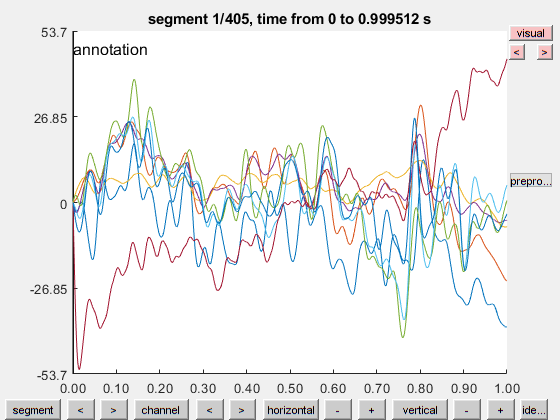

ft_databrowser (EEG_Data.cfg)



cfg = [];
cfg.dataset = 'U:\KDD\2nd Semester\Dissertation\example dataset\RSVP Aeroplane\5Hz\rsvp_5Hz_02a.edf';
cfg.trialdef.eventtype  = '?';
ft_definetrial(cfg);

evaluating trialfunction 'ft_trialfun_general'
reading the header from 'U:\KDD\2nd Semester\Dissertation\example dataset\RSVP Aeroplane\5Hz\rsvp_5Hz_02a.edf'


reading the events from 'U:\KDD\2nd Semester\Dissertation\example dataset\RSVP Aeroplane\5Hz\rsvp_5Hz_02a.edf'


no events were found in the datafile
no trials have been defined yet, see FT_DEFINETRIAL for further help
found 0 events
created 0 trials
the call to "ft_definetrial" took 0 seconds



data = ft_rejectartifact(cfg, EEG_Data)